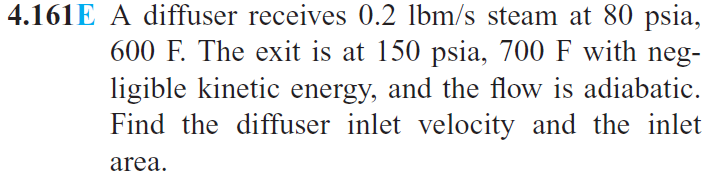

# given

u = symunit;
mdot = 0.2*u.lbm/u.s;
pi = 80*u.psi;
Ti = 600*u.Fahrenheit;
pe = 150*u.psi;
Te = 700*u.Fahrenheit;

# first law of thermodynamics

syms Vi positive;
hi = 1330.66*u.Btu/u.lbm; % superheated vapor water
he = 1376.55*u.Btu/u.lbm; % superheated vapor water
eqn_Vi = rewrite(simplify(mdot*(hi+Vi^2/2) == mdot*he), u.ft);
Vi = solve(eqn_Vi);
Vi_vpa = vpa(Vi, 6)

$$Vi\_vpa = 1515.88\,\frac{\mathrm{ft}}{s}$$

clearassum;

# inlet area

vi = 7.794*u.ft^3/u.lbm;
Ai = rewrite(mdot*vi/Vi, u.in);
Ai_vpa = vpa(Ai, 3)

$$Ai\_vpa = 0.148\,{\mathrm{in}}^{2}$$